fs = 44100;

%the number of samples and the passband cutoff frequency
M=525; Wp=0.0225*pi;

%the sampling points and the stopband cutoff frequency
m=0:(M+1)/2; Wm=2*pi*m./(M+1);

%round to negative part,i.e.floor(3.5)=3;floor(-3.2)=-4
mtr=floor(Wp*(M+1)/(2*pi))+2;
Ad= Wm<=Wp ;Ad(mtr)=1

Ad = 1×264 logical array
   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   


ind = find(Ad,1,'last')

ind = 7

disp([num2str(Wm(ind)/(2*pi)*fs),'Hz'])

503.0418Hz


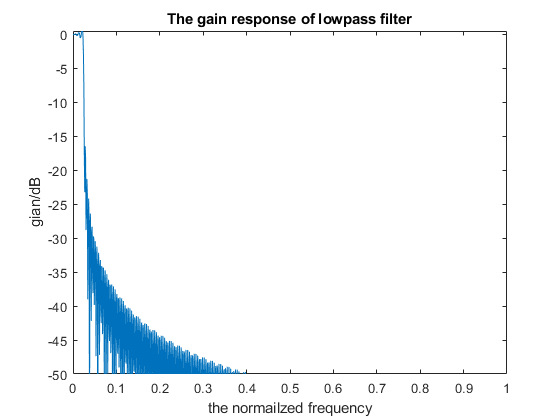


%define frequency-domain sampling vector H(k)
Hd=Ad.*exp(-1i*0.5*M*Wm);
%fliplr is to realize the fliplr of matrix and conj
Hd=[Hd conj(fliplr(Hd(2:(M+1)/2)))];

h=real(ifft(Hd));% h(n)=IDFT[H(k)]
w=linspace(0,pi,1000);%get 1000 row vectors between 0 and pi
H=freqz(h,1,w);%the amplitude -frequency characteristic diagram of the filter

H_L = H;

figure(1)
plot(w/pi,20*log10(abs(H)));%parameters are respectively the normalized frequency and amplitude
xlabel('the normailzed frequency');ylabel('gian/dB');title('The gain response of lowpass filter');
axis([0 1 -50 0.5]);

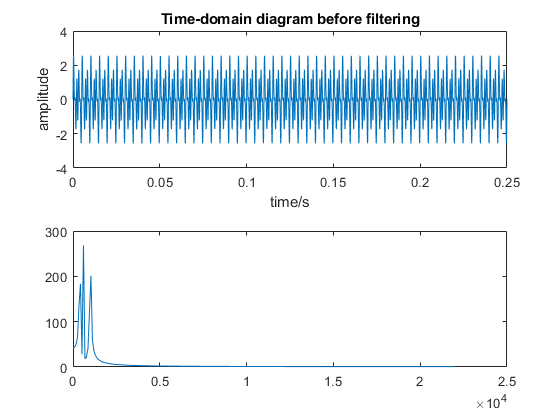

f1=400;f2=600;f3=1000;fs=44100;%the frequencies of sines signal that needs filtered and the sample frequency
figure(2)
subplot(2,1,1)
t=0:1/fs:0.25;%define the time domain and steplength
s=sin(2*pi*f1*t)+sin(2*pi*f2*t)+sin(2*pi*f3*t);%signal before filtering
plot(t,s);%plot the diagram before filtering
xlabel('time/s');ylabel('amplitude');title('Time-domain diagram before filtering');
subplot(2,1,2)
Fs=fft(s,512); AFs=abs(Fs);%transform to the frequency domain
f=(0:255)*fs/512;%frequency sampling
plot(f,AFs(1:256));%plot the frequency domain diagram before filtering

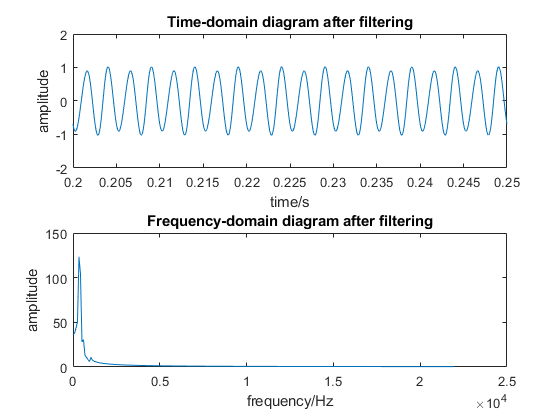

figure(3)
sf=filter(h,1,s);%use function filter
subplot(2,1,1)
plot(t,sf)%plot the diagram after filtering
xlabel('time/s');ylabel('amplitude');title('Time-domain diagram after filtering')
axis([0.2 0.25 -2 2]);%set the range of image coordinates
subplot(2,1,2)
Fsf=fft(sf,512); AFsf=abs(Fsf);%frequency-domain and the amplitude diagram
f=(0:255)*fs/512;%frequency sampling
plot(f,AFsf(1:256))%plot the frequency domain diagram before filtering
xlabel('frequency/Hz');ylabel('amplitude');title('Frequency-domain diagram after filtering');

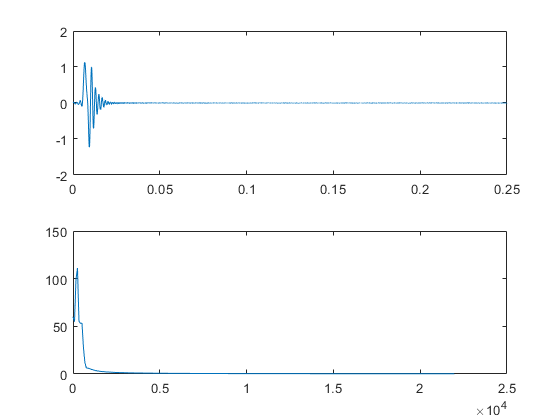

Y = chirp(t,10,t(end),20000);
sf = filter(h,1,Y);
figure(4)
subplot(2,1,1)
plot(t,sf)
subplot(2,1,2)
Fsf = fft(sf,512); AFsf = abs(Fsf);
plot(f,AFsf(1:256))

Lowpass_h = Hd;

## Desimoitu

%the number of samples and the passband cutoff frequency
M=225; Wp=0.025*pi;

%the sampling points and the stopband cutoff frequency
m=0:(M+1)/2; Wm=2*pi*m./(M+1)/4;

%round to negative part,i.e.floor(3.5)=3;floor(-3.2)=-4
mtr=floor(Wp*(M+1)/(2*pi))+2;
Ad= Wm<=Wp ;Ad(mtr)=1

Ad = 1×114 logical array
   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0



ind = find(Ad,1,'last')

ind = 12

disp([num2str(Wm(ind)/(2*pi)*fs),'Hz'])

536.615Hz


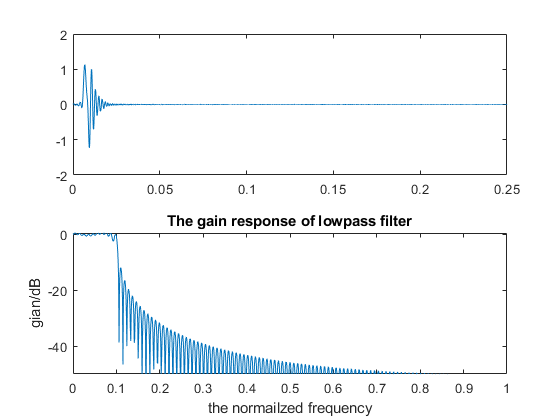


%define frequency-domain sampling vector H(k)
Hd=Ad.*exp(-1i*0.5*M*Wm);
%fliplr is to realize the fliplr of matrix and conj
Hd=[Hd conj(fliplr(Hd(2:(M+1)/2)))];

h=real(ifft(Hd));% h(n)=IDFT[H(k)]
w=linspace(0,pi,1000);%get 1000 row vectors between 0 and pi
H=freqz(h,1,w);%the amplitude -frequency characteristic diagram of the filter

figure(1)
plot(w/pi,20*log10(abs(H)));%parameters are respectively the normalized frequency and amplitude
xlabel('the normailzed frequency');ylabel('gian/dB');title('The gain response of lowpass filter');
axis([0 1 -50 0.5]);


Lowpass_h = Hd;